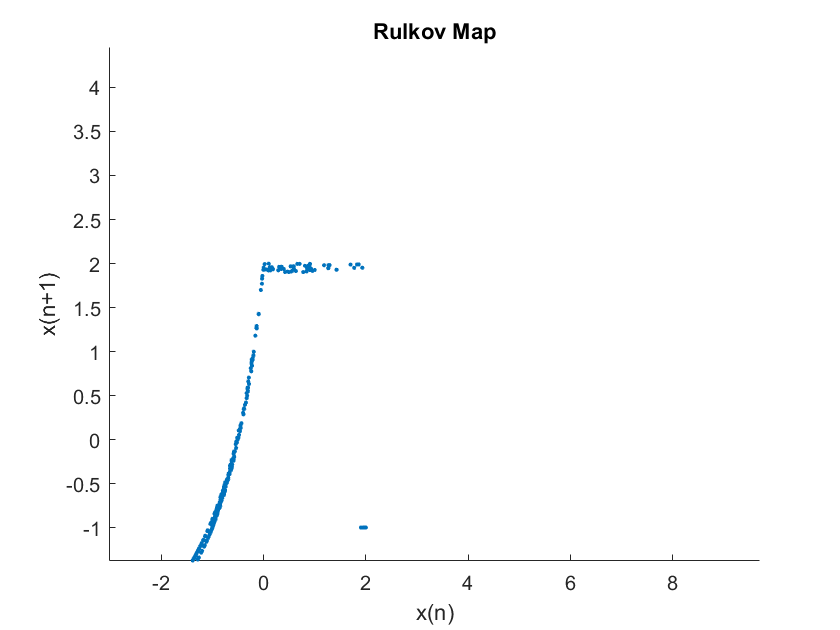

x(1)=20;
y(1)=-4.2;
a=5.8;
b=0.001;
c=0;
% and now we begin the iteration (10000 iterations):
for n=2:10000
    y(n+1)=y(n) - b*(x(n)-c +1);
        if x(n)<=0
        x(n+1) = (a/(1-x(n)))+y(n);
        elseif x(n)>0 && x(n)<a+y(n)
        x(n+1) = a+y(n);
        else
        x(n+1) = -1;
        end
end
hold on
plot(x(1:9999),x(2:10000),'.','MarkerSize',6)
title('Rulkov Map')
xlabel('x(n)') 
ylabel('x(n+1)') 
hold off

xlim([-3.02 9.70])
ylim([-1.38 4.46])

numel(x)

ans = 100001